## Prep data

input_training = randi([0 10],[50000,4])

input_training =      9     1     6     5
     0     3     5    10
     3     2     2     0
     1     0     7     0
     5     4    10    10
     4     7     0    10
    10     3     7     3
     2     9     5    10
     5     3     7     8
     7     2     9     7


output_training = randi([0 10],[50000,1])

output_training =      5
     7
     5
     6
     7
     4
     4
     9
     1
    10



trainBatch = 0.9;

m = size(input_training,1)

m = 50000

m_train = randsample(m,round(m*trainBatch));
Xtrain = input_training(m_train,:);
Ytrain = output_training(m_train,:);
Xtest = input_training;
Xtest(m_train,:) = [];
Ytest = output_training;
Ytest(m_train,:) = [];

## Create Layers

% define main path
mu = 0.5;
a = mu - 0.005;
b = mu + 0.005;

mainPath = [
    featureInputLayer(4,'Name','input')
    
    additionLayer(2,'Name','add_In_Inh')
    reluLayer('Name','R_out')
    
%     fullyConnectedLayer(1,'Name','C','Weights',a + (b-a).*rand(1,4))
    FCpositiveWeights(4,1,'C',a + (b-a).*rand(1,4))
    

    regressionLayer('Name','output')
    ]

mainPath =   5×1 Layer array with layers:

     1   'input'        Feature Input       4 features
     2   'add_In_Inh'   Addition            Element-wise addition of 2 inputs
     3   'R_out'        ReLU                ReLU
     4   'C'            FCpositiveWeights   Fully connected, positive-weighted layer
     5   'output'       Regression Output   mean-squared-error


inhPath = [
%     negationLayer('negation')
    
%     fullyConnectedLayer(4,'Name','R','Weights',a + (b-a).*rand(4))
%     FCpositiveWeights(4,4,'R',a + (b-a).*rand(4))
    FCInhibitoryInput(4,4,'I->R',a + (b-a).*rand(4))
    ]

inhPath =   FCInhibitoryInput with properties:

       Name: 'I->R'

   Learnable Parameters
    Weights: [4×4 double]
       Bias: [4×1 double]

  Show all properties


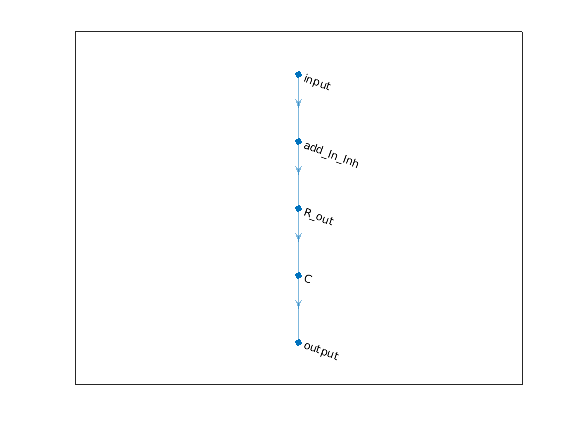


lgraph = layerGraph(mainPath);
plot(lgraph);


% Add inh path to main path
lgraph = addLayers(lgraph,inhPath)

lgraph =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [4×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}


lgraph = connectLayers(lgraph,'input','I->R')

lgraph =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}


lgraph = connectLayers(lgraph,'I->R','add_In_Inh/in2')

lgraph =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}



plot(lgraph)


## Analyze network

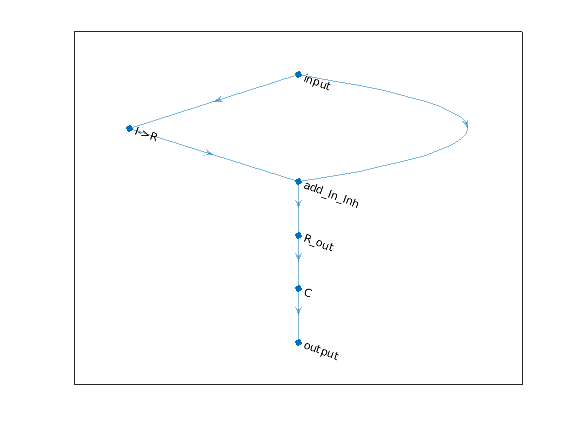

analyzeNetwork(lgraph)

## Initialize network by training it for 1 epoch

maxEpochs = 1;
miniBatchSize = 512;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'GradientThreshold',1, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'ValidationData',{Xtest,Ytest}, ...
    'ValidationFrequency',30, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(Xtrain,Ytrain,lgraph,options);

## Check network weights

net.Layers

ans =   6×1 Layer array with layers:

     1   'input'        Feature Input       4 features
     2   'add_In_Inh'   Addition            Element-wise addition of 2 inputs
     3   'R_out'        ReLU                ReLU
     4   'C'            FCpositiveWeights   Fully connected, positive-weighted layer
     5   'output'       Regression Output   mean-squared-error with response 'Response'
     6   'I->R'         FCInhibitoryInput   Fully connected, layer. Input is negated to simulate inhibition


RC_LayerIdx = 6  %choose appropriate index to get the desired layer

RC_LayerIdx = 6

net.Layers(RC_LayerIdx).Weights

ans = 4×4 single matrix
    0.4151    0.4134    0.4070    0.4138
    0.4102    0.4152    0.4171    0.4158
    0.4072    0.4093    0.4141    0.4130
    0.4164    0.4135    0.4132    0.4156


Overwrite weights

% IRnetcon = zeros(4);
% IRnetcon(1,3) = 1;
% IRnetcon(2,4) = 0.5;
% IRnetcon(1,2) = 1;
% IRnetcon(3,1) = 0.5;
% IRnetcon(4,3) = 1;
IRnetcon = rand(4);
RCnetcon = [1 0.2 0.1 0.7];

tmp_net = net.saveobj;
tmp_net.Layers(4).Weights = RCnetcon;
tmp_net.Layers(4).Bias = 0;
tmp_net.Layers(RC_LayerIdx).Weights = IRnetcon';
tmp_net.Layers(RC_LayerIdx).Bias = [0 0 0 0]';

set_net = net.loadobj(tmp_net);

Generate predict responses based on customized wieghts

out = predict(set_net,Xtrain);
Ytest = predict(set_net,Xtest);

Right now, "net" and "set_net" are different objects. Let's see if "net" can learn the weights of "set_net"

options = trainingOptions('adam', ...
    'InitialLearnRate',0.03, ...
    'ExecutionEnvironment','cpu', ...
    'GradientThreshold',1, ...
    'MaxEpochs',5, ...
    'MiniBatchSize',32, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'ValidationData',{Xtest,Ytest}, ...
    'ValidationFrequency',30, ...
    'Verbose',0, ...
    'Plots','training-progress');

RCinitweights = ones(4);
RCinitweights(2:3,2:3) = 0;

tmp_net.Layers(4).Weights = rand(1,4);
tmp_net.Layers(RC_LayerIdx).Weights = RCinitweights;
approx_net = net.loadobj(tmp_net);
lgraph2 = layerGraph(approx_net)

lgraph2 =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}


net = trainNetwork(Xtrain,out,lgraph2,options);


Analyze the weights of the trained network

net.Layers(4)

ans =   FCpositiveWeights with properties:

       Name: 'C'

   Learnable Parameters
    Weights: [0.6116 0.2661 0.1364 0.6846]
       Bias: 0.0051

  Show all properties


net.Layers(RC_LayerIdx).Weights

ans = 4×4 single matrix
    0.1745    0.5580    1.0861    0.1441
    0.7027    0.9723    0.7058    0.4178
    0.4479    0.6328    0.6512    0.3935
    0.1127    0.4172    0.6915    0.0523


net.Layers(RC_LayerIdx).Bias

ans = 4×1 single column vector
   -0.0030
   -0.0157
   -0.0326
    0.0003


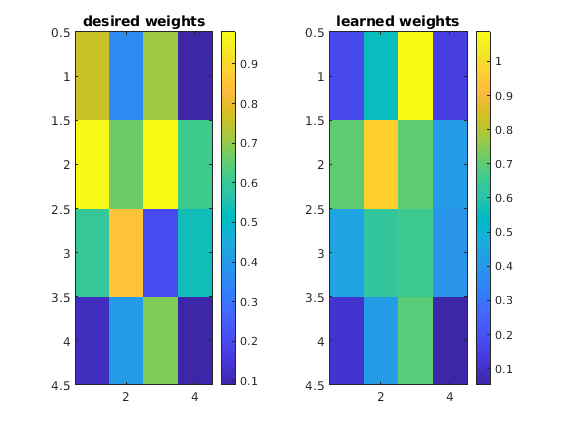


figure;
subplot(1,2,1)
imagesc(IRnetcon'); title('desired weights'); colorbar
subplot(1,2,2)
imagesc(net.Layers(RC_LayerIdx).Weights); title('learned weights')
colorbar

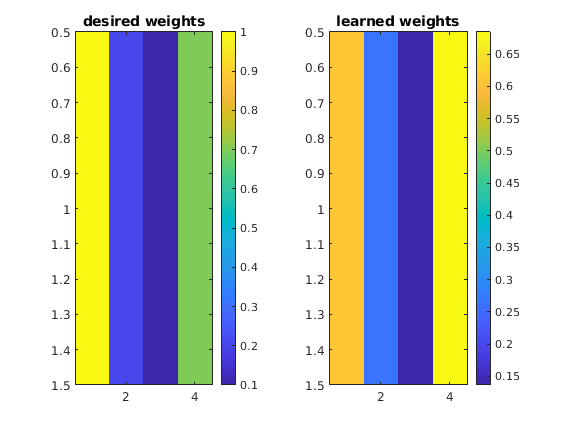


figure;
subplot(1,2,1)
imagesc(RCnetcon); title('desired weights'); colorbar
subplot(1,2,2)
imagesc(net.Layers(4).Weights); title('learned weights')
colorbar

Visualize outputs

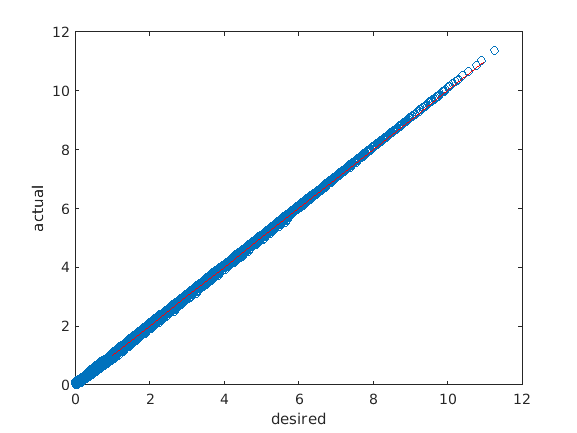

output_actual = predict(net,Xtrain);

figure
plot(out,output_actual,'o'); hold on;
plot(1:max(out),1:max(out),'r')
xlabel('desired')
ylabel('actual')